# Modelling

In order to model an Grainboundarie , the APT tip needs to be already reconstructed, and therefore the mass spectrum has to be ranged and the pos file parsed (so that a ion variable (column name) is generated). These steps can be found in the live script ***FirstSteps***.

If mass spectrum and pos file are not present follow the next steps

spec = gco;
posIn = posToTable;
rng = rangesExtractFromMassSpec(spec);
pos = posAllocateRange(posIn, rng, 'decompose');

## Create a hull of the Dataset

To obtain the outer boundary of the data set, an hull is created and placed an exportet as *.obj file. 

alpha = 50; % value of the radius, up to which concavties are allowed 
sample = 100000; % number of points of the sample
hull = patchCreateSampledAlphaHull(pos, alpha, sample);

Volume of dataset: 293075.4194 nm^3


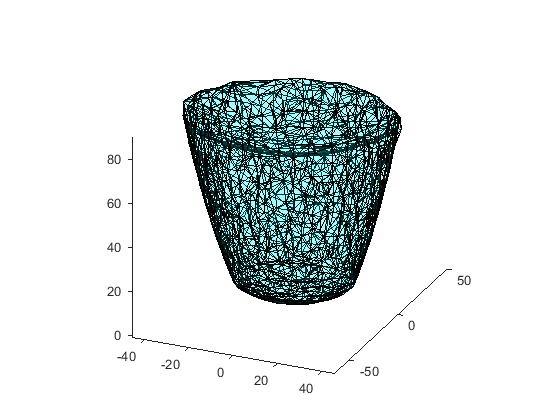

Error using fopen
File identifier must be an integer-valued scalar of type double.

Error in patchToObj (line 47)
fid = fopen(fileName,'wt');

patchToObj(hull); % export the hull to an .obj object

*More text*

Also one or more atom species can be selected and exported to *.obj 

posToObj(pos, {'C'}); % export all of the selected atoms in the data set as .obj 
 

After this the user has to switch to blender. The following steps were made with 2.91.0

## Steps in Blender

- Load the hull and the atoms into Blender

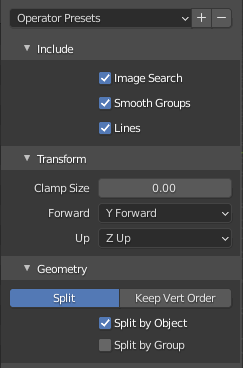

- Create a plane (Add-> Mesh -> Plane)

- Subdivide the plane (Edit Mode -> Right Click Plane -> Subdivide)

- Move and rotate the plane so that it fits the GB (Object Properties)

- Delete all of the points of the plane that are outside the hull (Edit Mode -> press C -> press Esc -> press delete)

- Add triangles at the outside of the plane so that it fits the hull better (Mark the 3 Vertices at the corners -> Press F)

- Export plane 

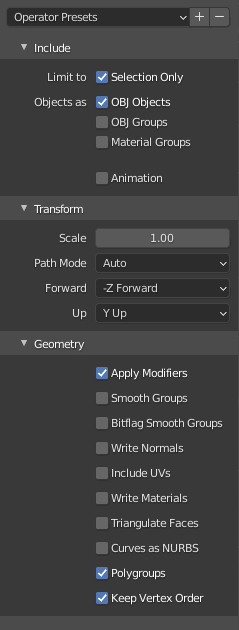

## Further adjustments to the grain boundary

At first the plane that was made in Blender needs to be imported

obj = objToPatch(); % loads *.obj datas in matlab
 

After this the Grainboundary is made from the vertices and faces of the plane and plotted in a figure.

GB.vertices = obj.vertices; % transfers vertices from obj structure to grainboundary structur 
GB.faces = obj.objects.faces; % transfers faces from obj structure to grainboundary structur
figure; % makes new figure
axisSpatialAptify
axis equal
patch(GB, 'FaceColor', 'r'); % plots the plane
 

With the algorithm described in *referenz peter paper* the grain boundary is modeled so that it fits the atom positions 

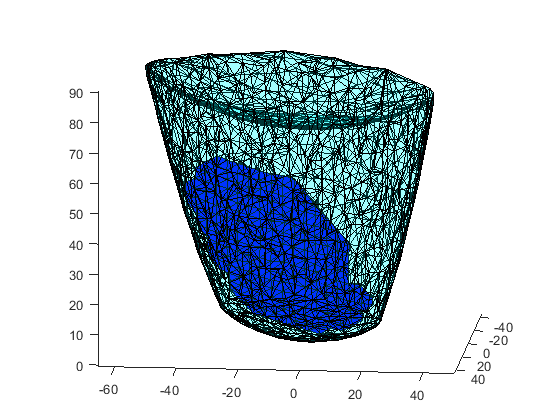

rad = ''; % radius that influences the DCOM step
GB2 = patchSnapToAtomPositions(GB,pos(pos.atom =='C',:),rad);
patch(GB2, 'FaceColor', 'b'); % plots the curved plane in the figure of the normal plane

Until now the grain boundary does not fit the outer hull of the atom probe data set. with the following step, the grain boundary is stretched to the hull of the data set. 

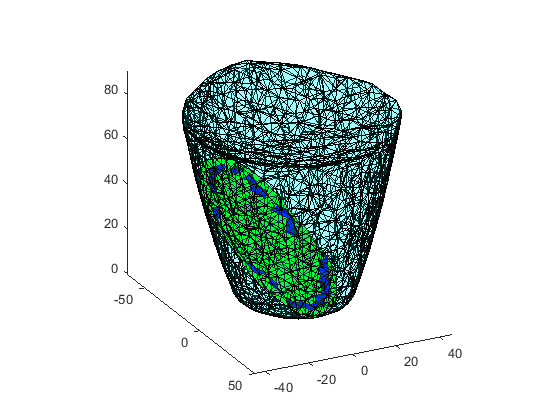

GB3 = patchStretchToHull(GB2, hull); %Grain boundary model stretched to the boundary of the hull
patch(GB3, 'FaceColor', 'g'); % plots the grain boundary in the hull (the older one GB must be deleted before);

Voronoi Tessellation *peters paper referenz*

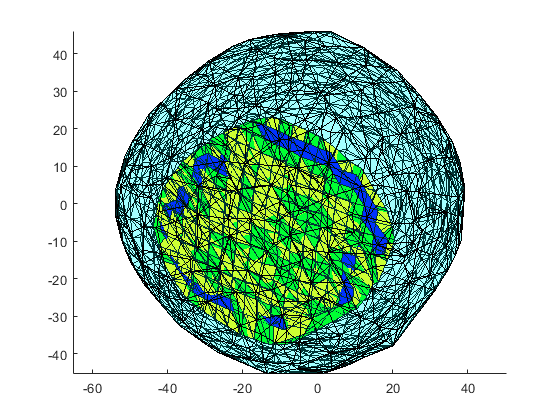

GB4 = patchCentroidalVoronoiTessellation(GB3, 1, 60);
patch(GB4, 'FaceColor', 'y'); 

If your grain boundary is bend you can repeat the voronoi tessellation in combination with patch SnapToAtomPositions to get a better representative mesh of your grain boundary

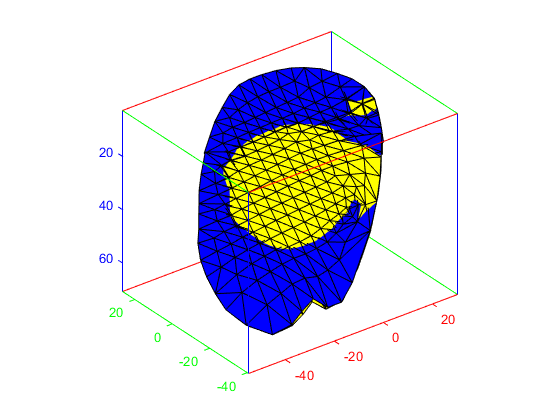

rad = 25; % radius that influences the DCOm step
GB5 = patchSnapToAtomPositions(GB4,pos(pos.atom =='C',:),rad);
GB6 = patchCentroidalVoronoiTessellation(GB5, 1, 60);
figure %shows the comparison between the beginning patch in blue and the new mesh after one iteration
patch(GB4, 'FaceColor', 'b');
patch(GB6, 'FaceColor', 'y');
axisSpatialAptify